# Lab 2 – 2D Convolution & FIR Filters (Blur, Sharpen, Edges)

Course: Mathematical Algorithms (DSP)

**Lecture: 9 – Image Processing LabsObjective**

The objective of this lab is to investigate how two-dimensional convolution and finite impulse response (FIR) filters are used in digital image processing.

The experiments cover impulse responses, low-pass filtering, image sharpening, edge detection, convolution, and boundary handling.

Different filters will be compared using MATLAB to understand their effects on image quality and spatial details.

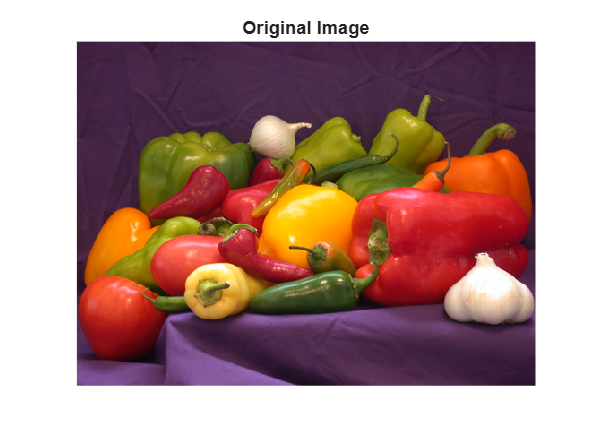


%% Lab 2: 2D Convolution & FIR Filters
% Section 0: Load and Prepare Image

close all;
clear;
clc;

% Load sample image
if exist('peppers.png', 'file')
    I0 = imread('peppers.png');
else
    I0 = repmat(imread('cameraman.tif'), 1, 1, 3);
end

% Convert RGB image to grayscale and double precision
I = im2double(rgb2gray(I0));

% Display original and grayscale images
figure;
imshow(I0);
title('Original Image');

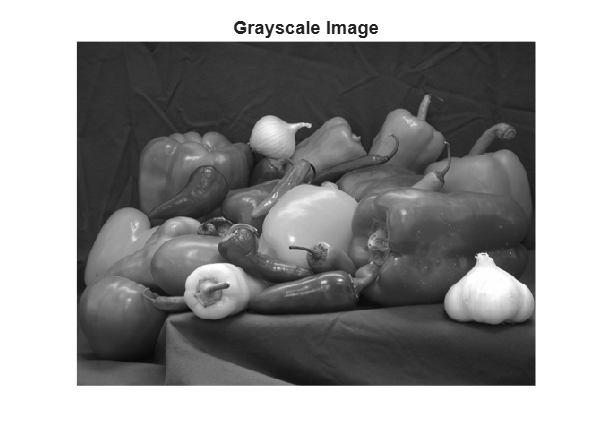


figure;
imshow(I);
title('Grayscale Image');


% Display image information
fprintf('Image size: %d x %d\n', size(I,1), size(I,2));

Image size: 384 x 512


fprintf('Data type: %s\n', class(I));

Data type: double


fprintf('Intensity range: %.3f to %.3f\n', ...
    min(I(:)), max(I(:)));

Intensity range: 0.031 to 1.000


**Section 0 – Image Preparation**

The image was loaded into MATLAB and converted from RGB to grayscale.

The grayscale image was then converted to double precision using `im2double`, representing pixel intensities in the range from 0 to 1.

This preparation allows convolution kernels and image filters to be applied using floating-point calculations.

The grayscale image will be used throughout the experiments to compare different filtering techniques.

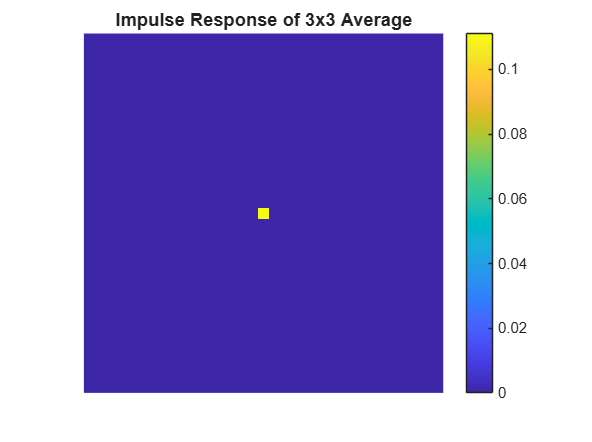


%% 1) Delta Image & Impulse Response

% Create a 101x101 image filled with zeros
delta = zeros(101,101);

% Set the center pixel to 1
delta(51,51) = 1;

% Create a 3x3 averaging filter
h_avg = ones(3,3)/9;

% Apply 2D convolution
H_vis = conv2(delta, h_avg, 'same');

% Display the impulse response
figure;
imagesc(H_vis);
axis image off;
colorbar;
title('Impulse Response of 3x3 Average');

**Section 1 – Delta Image and Impulse Response**

A 101×101 delta image was created with all pixel values set to zero except for the center pixel, which was set to 1.

A 3×3 averaging filter was then applied using two-dimensional convolution.

The resulting image shows a small 3×3 region at the center, corresponding to the averaging filter's impulse response. Each value in this region is 1/9.

This demonstrates that the impulse response of a two-dimensional FIR filter describes how the filter responds to a single nonzero pixel. It also shows the relationship between the convolution kernel and the filter's output.

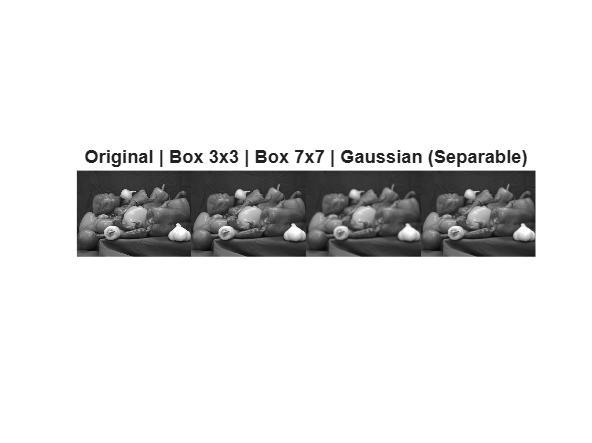


%% 2) Low-Pass: Box vs Gaussian, Separability

% Create averaging filters
h_box3 = ones(3,3)/9;
h_box7 = ones(7,7)/49;

% Gaussian filter parameters
sigma = 1.2;

% Create a 1D Gaussian kernel
g1d = fspecial('gaussian', [1 7], sigma);

% Create a separable 2D Gaussian kernel
h_gauss = g1d' * g1d;

% Apply filters
I_box3 = imfilter(I, h_box3, 'replicate');
I_box7 = imfilter(I, h_box7, 'replicate');
I_gauss = imfilter(I, h_gauss, 'replicate');

% Display results
figure;
montage({I, I_box3, I_box7, I_gauss}, 'Size', [1 4]);

title('Original | Box 3x3 | Box 7x7 | Gaussian (Separable)');

**Section 2 – Low-Pass Filtering: Box vs Gaussian**

Three low-pass filters were applied to the grayscale image: a 3×3 box filter, a 7×7 box filter, and a Gaussian filter with sigma = 1.2.

The 3×3 box filter produces mild smoothing, while the 7×7 box filter produces stronger blurring because it averages pixels over a larger neighborhood.

The Gaussian filter assigns greater weight to pixels near the center of the kernel, resulting in a smoother weighted average.

The Gaussian kernel was constructed from the outer product of a one-dimensional Gaussian kernel and its transpose. This demonstrates separability, which allows two-dimensional filtering to be implemented using two one-dimensional passes.

Separability can reduce computational cost, particularly for larger filters. The experiment also demonstrates how low-pass filters suppress high-frequency image details and reduce sharpness.

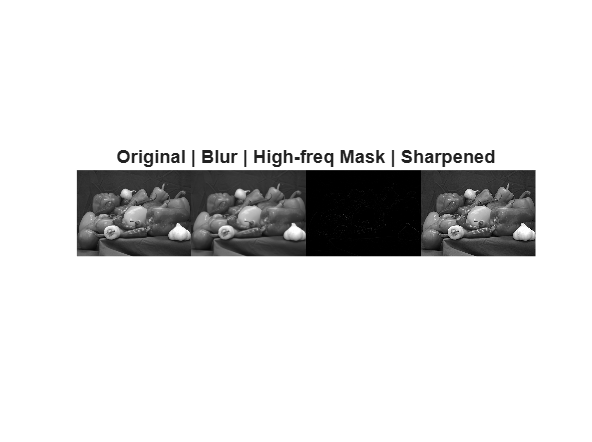


%% 3) Unsharp Masking (Sharpen)

% Blur the original image using the Gaussian filter
I_blur = imfilter(I, h_gauss, 'replicate');

% Extract high-frequency details
mask = I - I_blur;

% Set sharpening strength
gain = 1.0;

% Add high-frequency details back to original image
I_sharp = max(min(I + gain*mask, 1), 0);

% Display comparison
figure;
montage({I, I_blur, mask, I_sharp}, 'Size', [1 4]);

title('Original | Blur | High-freq Mask | Sharpened');

**Section 3 – Unsharp Masking (Image Sharpening)**

Unsharp masking was applied to the grayscale image to enhance edges and fine details.

First, the image was blurred using the Gaussian filter created in Section 2. The blurred image was then subtracted from the original image to produce a high-frequency mask.

This mask contains information about intensity changes, particularly around edges and fine image details.

The mask was added back to the original image using a sharpening gain of 1.0. The resulting pixel values were limited to the range from 0 to 1.

The sharpened image is expected to have more pronounced edges than the original. However, excessive sharpening can also increase noise and introduce unwanted artifacts.

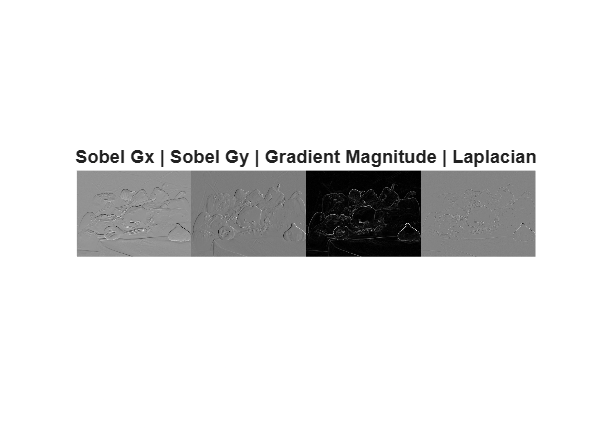


%% 4) Edges: Sobel & Laplacian

% Create Sobel kernels
h_sobel_x = fspecial('sobel');
h_sobel_y = h_sobel_x';

% Apply Sobel filters
Gx = imfilter(I, h_sobel_x, 'replicate');
Gy = imfilter(I, h_sobel_y, 'replicate');

% Calculate gradient magnitude
Gmag = hypot(Gx, Gy);

% Create Laplacian kernel
h_lap = fspecial('laplacian', 0.2);

% Apply Laplacian filter
I_lap = imfilter(I, h_lap, 'replicate');

% Display results
figure;
montage({mat2gray(Gx), mat2gray(Gy), ...
    mat2gray(Gmag), mat2gray(I_lap)}, 'Size', [1 4]);

title('Sobel Gx | Sobel Gy | Gradient Magnitude | Laplacian');

**Section 4 – Edge Detection Using Sobel and Laplacian Filters**

Sobel and Laplacian filters were applied to the grayscale image to investigate edge detection.

The Sobel filters estimate intensity changes in two perpendicular spatial directions. Their responses were combined using the gradient magnitude to highlight edges independently of their orientation.

The Laplacian filter was also applied to detect rapid intensity changes using a second-order derivative.

The results demonstrate that Sobel filtering provides directional edge information, while the Laplacian responds to changes in intensity curvature.

These filters are useful for identifying object boundaries and image structures. However, derivative-based filters can also respond strongly to noise.


%% 5) Correlation vs Convolution (Kernel Flip)

% Apply 2D convolution using conv2
C1 = conv2(I, h_box3, 'same');

% Apply convolution using imfilter
% The 'conv' option flips the kernel internally
C2 = imfilter(I, h_box3, 'conv', 'same');

% Calculate the maximum absolute difference
diff_val = max(abs(C1(:) - C2(:)));

% Display the result
fprintf('Max difference (conv2 vs imfilter with conv): %g\n', diff_val);

Max difference (conv2 vs imfilter with conv): 3.33067e-16


**Section 5 – Correlation vs Convolution**

Two-dimensional convolution was performed using MATLAB's `conv2` function and the `imfilter` function with the convolution option.

The same 3×3 averaging kernel was used in both operations, and the maximum absolute difference between the outputs was calculated.

The results are expected to be identical or nearly identical because both functions perform convolution with equivalent boundary handling.

In convolution, the filter kernel is flipped before it is applied, while correlation uses the kernel without flipping.

Since the averaging kernel is symmetric, flipping it does not change its values. Therefore, this particular kernel would also produce the same output under correlation when the boundary conditions are identical.

This experiment demonstrates the relationship between convolution, correlation, and kernel symmetry.


%% 6) Boundary Handling

% Apply 7x7 box filter using replicate padding
I_rep = imfilter(I, h_box7, 'replicate');

% Apply 7x7 box filter using symmetric padding
I_sym = imfilter(I, h_box7, 'symmetric');

% Apply 7x7 box filter using circular padding
I_cir = imfilter(I, h_box7, 'circular');

% Display comparison
figure;
montage({I_rep, I_sym, I_cir}, 'Size', [1 3]);

title('Boundary: Replicate | Symmetric | Circular');

**Section 6 – Boundary Handling**

Three boundary handling methods were compared using a 7×7 averaging filter: replicate, symmetric, and circular padding.

Replicate padding extends the image by repeating the nearest border pixels. Symmetric padding reflects pixel values across the image boundaries, while circular padding uses pixels from the opposite side of the image.

The filtering results are expected to be similar in the central regions because boundary handling does not affect pixels whose entire filter neighborhood lies inside the image.

Differences mainly occur near the image borders and corners, where the filter requires values outside the original image.

This experiment demonstrates that boundary handling is an important part of image filtering because different padding methods can produce different edge artifacts.

## Section 7 – Reflections

**1. Why is Gaussian filtering preferred over a large box low-pass filter?**

Gaussian filtering is often preferred because it produces smoother blurring and has a smoother frequency response.

A box filter gives equal weight to all pixels within its kernel, while a Gaussian filter assigns higher weights to pixels near the center and gradually reduces the weights toward the edges.

Large box filters can introduce stronger unwanted frequency-response sidelobes. Gaussian filters generally provide smoother attenuation of high spatial frequencies.

In this experiment, the 7×7 box filter produces stronger averaging than the 3×3 box filter, while the Gaussian filter provides weighted smoothing

**2. How does separability reduce computational cost?**

Separability allows a two-dimensional filter to be implemented using two one-dimensional filtering operations.

In this experiment, the Gaussian kernel was constructed using the outer product of a one-dimensional Gaussian kernel and its transpose.

For a 7×7 kernel, direct two-dimensional filtering requires approximately 49 multiplications per output pixel.

Using two one-dimensional passes requires approximately 14 multiplications per output pixel.

Therefore, separability can significantly reduce computational cost, especially when using larger filter kernels.

**3. How do boundary handling modes affect image borders and corners?**

Boundary handling determines how pixel values outside the image are estimated during filtering.

Replicate padding repeats the nearest border pixels, while symmetric padding reflects image values across the boundaries.

Circular padding wraps pixels from the opposite side of the image.

These methods generally produce similar results in the central regions, where the filter kernel stays completely inside the image.

However, differences can occur near borders and corners because each method uses different values outside the image.

This demonstrates that boundary handling influences filtering results and can introduce different artifacts near image boundaries.